# some numbers.

## all times are in [ms]

dt  = 2;
tmax = 1998;
tmin = -1200;
fs = 1/dt;
len_sample = floor((tmax-tmin)*fs);
t = linspace(tmin, tmax, len_sample);

ratio_windows = linspace(0,0.5,11);
jitters = ratio_windows*200;
N2_widths = 100:25:500;

noise.amplitude = [0.5 1];
noise.jitters = zeros(1,10);
noise.jitter = 0;
% noise.randn = 0.1;
noise.pink_alpha = -2.4;

num_trails = 500;
freqs = logspace(log10(2), log10(60), 30);

bl_range = find( -900 < t & t < -750);
u = t > -200 & t < 1000;

tot_erp = zeros(length(N2_widths), length(jitters));
tot_orig = zeros(size(tot_erp));
tot_sub = zeros(size(tot_erp));
tot_diff = zeros(size(tot_erp));

## run the script for different N2 widths

calculating and plotting ERPs

parfor ii_width = 1:length(N2_widths)
    
    tic
    N2_width = N2_widths(ii_width);
    tscales_vector = round([N2_width.*(1-ratio_windows'), N2_width./(1-ratio_windows)']);
    
    %% generating trials
    erps = zeros(length(jitters), length(t));
    trials = zeros(length(jitters), num_trails, length(t));
    sub_trials = trials;
    for ii = 1:length(jitters)
        noise2 = noise;
        noise2.tscales = tscales_vector(ii,:);
        trials(ii,:,:) = N200matWithNoise(t, num_trails, noise2);
        erps(ii,:) = mean(trials(ii,:,:));
        sub_trials(ii,:,:) = bsxfun(@minus, squeeze(trials(ii,:,:)), erps(ii,:));
    end
    baseN2 = squeeze(trials(1,1,:));
    
    % plotting all erps
    figure;
    plot(t(u),baseN2(u),'k-')
    hold on
    plot(t(u),erps(:,u)')
    xlabel time[ms]
    ylabel [Au]
    title(sprintf('ERPs for different window sizes'));
    
    legend_str = cellstr(num2str(100-100*jitters'/N2_width, 'scale=%.3g%%'));
    legend_str_all = [{num2str(N2_width, 'base N2 (%d)')} ; legend_str];
    legend(legend_str_all);

    hold off
    
    %% spectral analysis
    originals_freq_power = zeros([length(jitters) length(freqs) length(t)]);
    subtrials_freq_power = originals_freq_power;
    total_phase = zeros([size(originals_freq_power), num_trails]);
    
    erps_freq_power = getPowerSpectra(erps,dt, freqs); %freq-time(-channel)
    if(ndims(erps_freq_power))==2
        %for ploting competability
        erps_freq_power = reshape(erps_freq_power,[1 size(erps_freq_power)]);
    else
        erps_freq_power = shiftdim(erps_freq_power,2); %channel-freq-time
    end
    
    for ii = 1:length(jitters)
        [amp,ph] = getPowerSpectra(squeeze(trials(ii,:,:)),dt,freqs);   
        bl_values = mean(mean(amp(:, bl_range, :),3),2);
        originals_freq_power(ii,:,:) = 10 * log10(bsxfun(@rdivide,mean(amp,3),bl_values));
        total_phase(ii,:,:,:) = ph;
        
        amp = getPowerSpectra(squeeze(sub_trials(ii,:,:)),dt,freqs);
    %     bl_values = mean(mean(amp(:, bl_range, :),3),2);
        subtrials_freq_power(ii,:,:) = 10 * log10(bsxfun(@rdivide,mean(amp,3),bl_values));
        
        erps_freq_power(ii,:,:) = 10 * log10(bsxfun(@rdivide,squeeze(erps_freq_power(ii,:,:)),bl_values));
    end
    
    diff_original_subtracted_trials = originals_freq_power - subtrials_freq_power;
            
    %% compare jitter size to sum of spectral information    
    tot_freq_sum = @(P) squeeze(sum(sum(P(:,:,u),3),2)); 
    
    tot_erp(ii_width, :) = tot_freq_sum(erps_freq_power);
    tot_orig(ii_width, :) = tot_freq_sum(originals_freq_power);
    tot_sub(ii_width, :) = tot_freq_sum(subtrials_freq_power);
    tot_diff(ii_width, :) = tot_freq_sum(diff_original_subtracted_trials);
    
    toc
end

Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers.
Elapsed time is 735.763961 seconds.
Elapsed time is 742.279197 seconds.
Elapsed time is 777.859256 seconds.
Elapsed time is 783.493195 seconds.
Elapsed time is 622.585512 seconds.
Elapsed time is 623.929515 seconds.
Elapsed time is 617.993609 seconds.
Elapsed time is 615.790884 seconds.
Elapsed time is 599.947776 seconds.
Elapsed time is 599.123915 seconds.
Elapsed time is 600.273937 seconds.
Elapsed time is 599.717739 seconds.
Elapsed time is 576.350279 seconds.
Elapsed time is 591.133937 seconds.
Elapsed time is 572.627683 seconds.
Elapsed time is 683.423440 seconds.
Elapsed time is 490.472180 seconds.


save window_rep_total_power.mat tot_erp tot_orig tot_sub tot_diff ratio_windows
load window_rep_total_power.mat

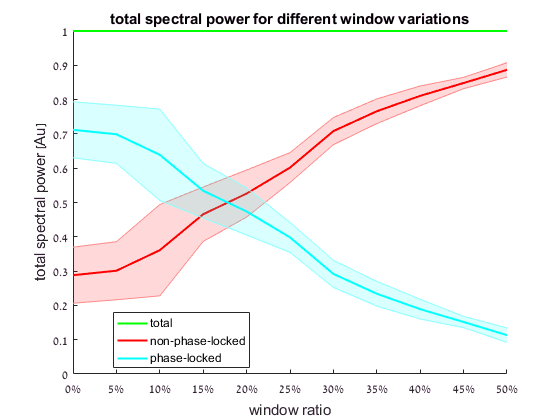

%% normalize powers by the original mean power
base_factor = tot_orig;
tot_erp_n = tot_erp./base_factor;
tot_orig_n = tot_orig./base_factor;
tot_sub_n = tot_sub./base_factor;
tot_diff_n = tot_diff./base_factor;

% plt_colors = {'b','g','r','c'};
figure
clear H
% H(1) = stdshade(tot_erp_n, 0.2, 'b', ratio_windows, 3);
% H(2) = stdshade(tot_orig_n, 0.2, 'g', ratio_windows, 3);
% H(3) = stdshade(tot_sub_n, 0.2, 'r', ratio_windows, 3);
% H(4) = stdshade(tot_diff_n, 0.2, 'c', ratio_windows, 3);
ci_alpha = 0.95;
ci = @(data)(output(@()ttest(data,0,'alpha',1-ci_alpha),3));

hold on
% H(1) = shadedErrorBar(jitters, tot_erp_n, {@mean, std}, {'-b', 'LineWidth', 1.5}, 1);
H(2) = shadedErrorBar(ratio_windows*100, tot_orig_n, {@mean, ci, true}, {'-g', 'LineWidth', 1.5}, 1);
H(3) = shadedErrorBar(ratio_windows*100, tot_sub_n, {@mean, ci, true}, {'-r', 'LineWidth', 1.5}, 1);
H(4) = shadedErrorBar(ratio_windows*100, tot_diff_n, {@mean, ci, true}, {'-c', 'LineWidth', 1.5}, 1);

% title 'total spectral power for different 12 repetitions with 100 trials each'
title 'total spectral power for different window variations'
% xlabel 'jitter [ms]'
xlabel 'window ratio'
xtickformat('%.2g%%')
ylabel 'total spectral power [Au]'
% strlegend = {'ERP', 'total', 'non-phased-locked', 'phase-locked'};
strlegend = {'total', 'non-phase-locked', 'phase-locked'};
legend([H.mainLine], strlegend, 'Location', 'Best')